## Initialization (do everything in the root folder)

set_path
clc
clear
close all

global external_force;
external_force=0;

global sigma;
global internal_noise_flag;
sigma=0;
internal_noise_flag=0;

global cpg_percent;
cpg_percent = 0.33;

## Run without optimization

run_simulation

## Velocity performace

% Cost function parameters (only for information purpose):
%w1 = 7;
%w2 = 1;
%w3 = 5;
%w4 = 0;
%w5 = 0;
%target_height = 0.5;

### Max velocity (1m/s)

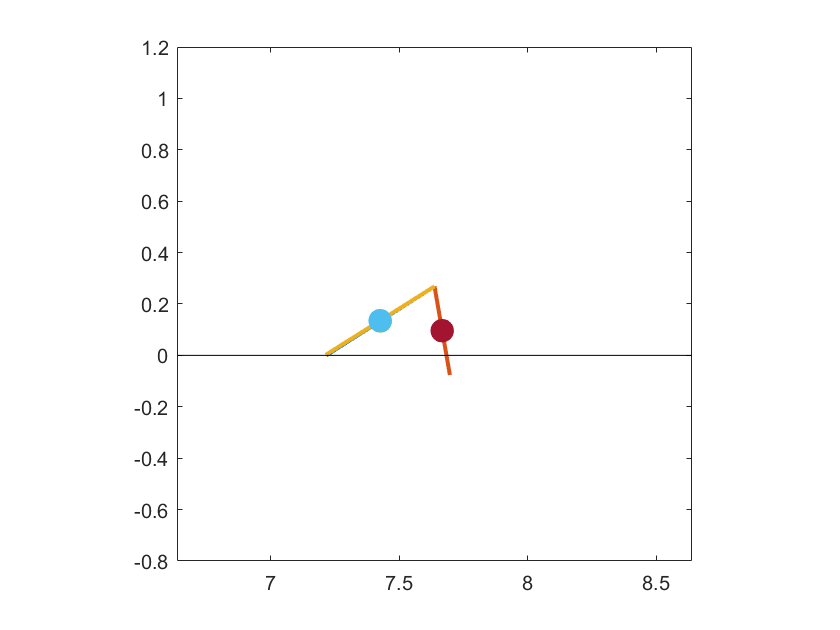

Real time factor:    0.4889



% Cost function parameters (only for information purpose):
%target_mean_velocity = 1.2; 

%Results:
r1=open('Results/max_vel/q0_max_vel.mat');
q0=r1.q0;
r2=open('Results/max_vel/dq0_max_vel.mat');
dq0=r2.dq0;
r3=open('Results/max_vel/x0_max_vel.mat');
x0=r3.x0;
r4=open('Results/max_vel/param_max_vel.mat');
y_opt=r4.y_opt;
sln = solve_eqns(q0, dq0, x0, 30, y_opt);
animate(sln);

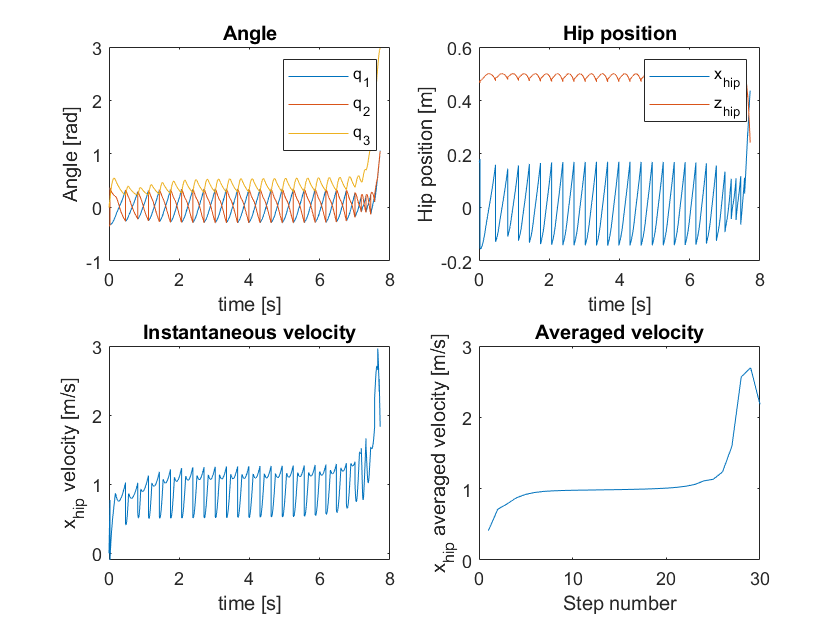

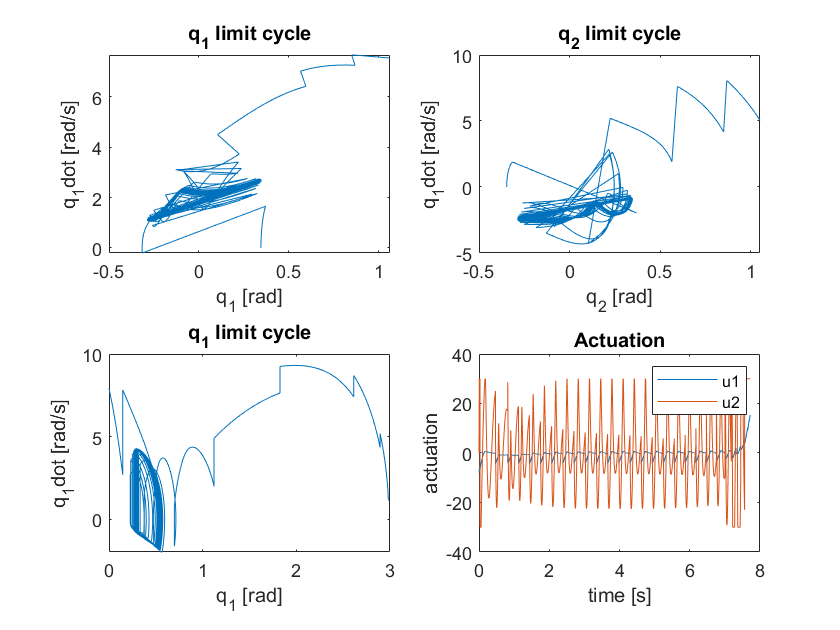

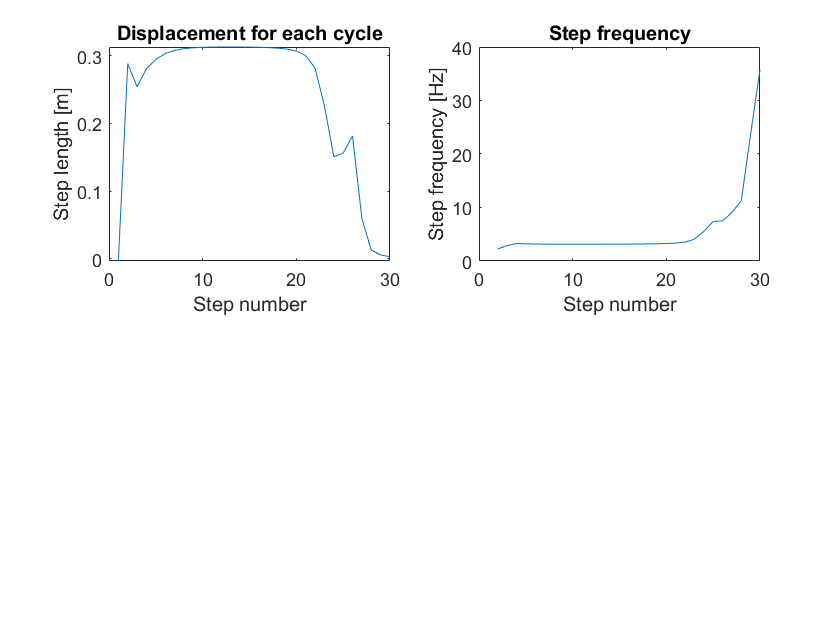

analyse(sln,y_opt,1);

### Min velocity (0.38m/s)

% Cost function parameters(only for information purpose):
%target_mean_velocity = 0.1; 


%Results:
r1=open('Results/min_vel/q0_min_vel.mat');
q0=r1.q0;
r2=open('Results/min_vel/dq0_min_vel.mat');
dq0=r2.dq0;
r3=open('Results/min_vel/x0_min_vel.mat');
x0=r3.x0;
r4=open('Results/min_vel/param_min_vel.mat');
y_opt=r4.y_opt;
sln = solve_eqns(q0, dq0, x0, 30, y_opt);
animate(sln);
analyse(sln,y_opt,1);

## Step length performace

% Cost function parameters(only for information purpose):
%w1 = 0;
%w2 = 1;
%w3 = 0;
%w4 = 0;
%w5 = 10;

### Max step length (0.42m)

% Cost function parameters(only for information purpose):
%target_step_length = 1;

%Results:
r1=open('Results/max_length/q0_max_length.mat');
q0=r1.q0;
r2=open('Results/max_length/dq0_max_length.mat');
dq0=r2.dq0;
r3=open('Results/max_length/x0_max_length.mat');
x0=r3.x0;
r4=open('Results/max_length/param_max_length.mat');
y_opt=r4.y_opt;
sln = solve_eqns(q0, dq0, x0, 30, y_opt);
animate(sln);
analyse(sln,y_opt,1);

### Min step length (0.3m)

% Cost function parameters(only for information purpose):
%target_step_length = 0.1;

%Results:
r1=open('Results/min_length/q0_min_length.mat');
q0=r1.q0;
r2=open('Results/min_length/dq0_min_length.mat');
dq0=r2.dq0;
r3=open('Results/min_length/x0_min_length.mat');
x0=r3.x0;
r4=open('Results/min_length/param_min_length.mat');
y_opt=r4.y_opt;
sln = solve_eqns(q0, dq0, x0, 30, y_opt);
animate(sln);
analyse(sln,y_opt,1);

## Step frequency performance

% Cost function parameters(only for information purpose):
%w1 = 7;
%w2 = 1;
%w3 = 5;
%w4 = 0;
%w5 = 0;
%target_height = 0.5;

### Max step frequency (3.2Hz)

% Cost function parameters(only for information purpose):
% target_frequency = 5; 


%Results:
r1=open('Results/max_frq/q0_max_frq.mat');
q0=r1.q0;
r2=open('Results/max_frq/dq0_max_frq.mat');
dq0=r2.dq0;
r3=open('Results/max_frq/x0_max_frq.mat');
x0=r3.x0;
r4=open('Results/max_frq/param_max_frq.mat');
y_opt=r4.y_opt;
sln = solve_eqns(q0, dq0, x0, 30, y_opt);
animate(sln);
analyse(sln,y_opt,1);

### Min step frequency (1.54Hz)

% Cost function parameters(only for information purpose):
%target_frequency = 1; 


%Results:
r1=open('Results/min_frq/q0_min_frq.mat');
q0=r1.q0;
r2=open('Results/min_frq/dq0_min_frq.mat');
dq0=r2.dq0;
r3=open('Results/min_frq/x0_min_frq.mat');
x0=r3.x0;
r4=open('Results/min_frq/param_min_frq.mat');
y_opt=r4.y_opt;
sln = solve_eqns(q0, dq0, x0, 30, y_opt);
animate(sln);
analyse(sln,y_opt,1);

## External disturbance performance

% Cost function parameters(only for information purpose):
%w1 = 0;
%w2 = 3;
%w3 = 5;
%w4 = 0;
%w5 = 0;
%target_height = 0.5;

### Positive external disturbance (+6N)

external_force=6;

%Results:
r1=open('Results/max_ext/q0_max_ext.mat');
q0=r1.q0;
r2=open('Results/max_ext/dq0_max_ext.mat');
dq0=r2.dq0;
r3=open('Results/max_ext/x0_max_ext.mat');
x0=r3.x0;
r4=open('Results/max_ext/param_max_ext.mat');
y_opt=r4.y_opt;
sln = solve_eqns(q0, dq0, x0, 30, y_opt);
animate(sln);
analyse(sln,y_opt,1);

### Negative external disturbance (-40N)

external_force=-40;

%Results:
r1=open('Results/min_ext/q0_min_ext.mat');
q0=r1.q0;
r2=open('Results/min_ext/dq0_min_ext.mat');
dq0=r2.dq0;
r3=open('Results/min_ext/x0_min_ext.mat');
x0=r3.x0;
r4=open('Results/min_ext/param_min_ext.mat');
y_opt=r4.y_opt;
sln = solve_eqns(q0, dq0, x0, 30, y_opt);
animate(sln);
analyse(sln,y_opt,1);

## Internal disturbance performance

% Cost function parameters(only for information purpose):
%w1 = 0;
%w2 = 3;
%w3 = 5;
%w4 = 0;
%w5 = 0;
%target_height = 0.5;

### Disturbance on q1

sigma = 0.013; 
internal_noise_flag = 1;

%Results:
r1=open('Results/max_int/q0_max_int1.mat');
q0=r1.q0;
r2=open('Results/max_int/dq0_max_int1.mat');
dq0=r2.dq0;
r3=open('Results/max_int/x0_max_int1.mat');
x0=r3.x0;
r4=open('Results/max_int/param_max_int1.mat');
y_opt=r4.y_opt;
sln = solve_eqns(q0, dq0, x0, 30, y_opt);
animate(sln);
analyse(sln,y_opt,1);

### Disturbance on q2

sigma = 0.013; 
internal_noise_flag = 2;

%Results:
r1=open('Results/max_int/q0_max_int2.mat');
q0=r1.q0;
r2=open('Results/max_int/dq0_max_int2.mat');
dq0=r2.dq0;
r3=open('Results/max_int/x0_max_int2.mat');
x0=r3.x0;
r4=open('Results/max_int/param_max_int2.mat');
y_opt=r4.y_opt;
sln = solve_eqns(q0, dq0, x0, 30, y_opt);
animate(sln);
analyse(sln,y_opt,1);

### Disturbance on q3

sigma = 0.03; 
internal_noise_flag = 3;

%Results:
r1=open('Results/max_int/q0_max_int3.mat');
q0=r1.q0;
r2=open('Results/max_int/dq0_max_int3.mat');
dq0=r2.dq0;
r3=open('Results/max_int/x0_max_int3.mat');
x0=r3.x0;
r4=open('Results/max_int/param_max_int3.mat');
y_opt=r4.y_opt;
sln = solve_eqns(q0, dq0, x0, 30, y_opt);
animate(sln);
analyse(sln,y_opt,1);

### Disturbance on dq1

sigma = 0.04; 
internal_noise_flag = 4;

%Results:
r1=open('Results/max_int/q0_max_intd1.mat');
q0=r1.q0;
r2=open('Results/max_int/dq0_max_intd1.mat');
dq0=r2.dq0;
r3=open('Results/max_int/x0_max_intd1.mat');
x0=r3.x0;
r4=open('Results/max_int/param_max_intd1.mat');
y_opt=r4.y_opt;
sln = solve_eqns(q0, dq0, x0, 30, y_opt);
animate(sln);
analyse(sln,y_opt,1);

### Disturbance on dq2

sigma = 0.7; 
internal_noise_flag = 5;

%Results:
r1=open('Results/max_int/q0_max_intd2.mat');
q0=r1.q0;
r2=open('Results/max_int/dq0_max_intd2.mat');
dq0=r2.dq0;
r3=open('Results/max_int/x0_max_intd2.mat');
x0=r3.x0;
r4=open('Results/max_int/param_max_intd2.mat');
y_opt=r4.y_opt;
sln = solve_eqns(q0, dq0, x0, 30, y_opt);
animate(sln);
analyse(sln,y_opt,1);

### Disturbance on dq3

sigma = 0.2; 
internal_noise_flag = 6;

%Results:
r1=open('Results/max_int/q0_max_intd3.mat');
q0=r1.q0;
r2=open('Results/max_int/dq0_max_intd3.mat');
dq0=r2.dq0;
r3=open('Results/max_int/x0_max_intd3.mat');
x0=r3.x0;
r4=open('Results/max_int/param_max_intd3.mat');
y_opt=r4.y_opt;
sln = solve_eqns(q0, dq0, x0, 30, y_opt);
animate(sln);
analyse(sln,y_opt,1);

Thanks for checking!